# Solution to *Spectral Measurement* Exercise

The spreadsheet `spectra.xlsx` contains 10 columns, each representing the measured spectrum of a star. The value in each row is the observed intensity of a particular wavelength of light. The header information provides the wavelength of the first row ($\lambda_0$) and the difference between subsequent values of the wavelength ($\Delta\lambda$). Wavelengths are given in nm.

## 1. Import the first column from `spectra.xlsx`

Use the Import Tool to import the first column (HD30584) from the file `spectra.xlsx`.

Below is the programmatic version of importing the first column.

data = xlsread('spectra.xlsx');
HD30584 = data(:,1);

## 2. Create four scalar variables

Create four scalar variables:

- `lambdastart `containing the value of $\lambda_0$ (630.02)

- `dlambda `containing the value of $\Delta\lambda$ (0.14)

- `nObs `containing the value of the number of observations (357)

- `lambdaend` that contains the last value of the wavelength (that is, the wavelength corresponding to the last observation), according to the formula


$$\lambda_{end} = \lambda_0 + (n_{Obs} - 1)\Delta\lambda$$


nObs = 357;
lambdastart = 630.02;
dlambda = 0.14;
lambdaend = lambdastart + (nObs-1)*dlambda;

## 3. Create a column vector of lambda values

Create a column vector `lambda` that starts at `lambdastart`, and goes in steps of `dlambda` to `lambdaend`.

lambda = (lambdastart:dlambda:lambdaend)';

## 4. Plot HD30584 vs lambda and label plot

Plot `HD30584` as a function of `lambda`. Label your plot.

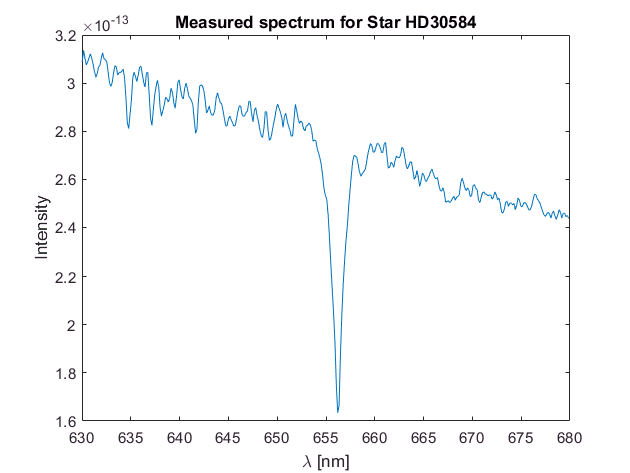

plot(lambda,HD30584)
xlabel('\lambda [nm]')
ylabel('Intensity')
title('Measured spectrum for Star HD30584')

## 5. Plot a line that goes through the dip

To draw a line on your plot from $(x_1,y_1)$ to $(x_2,y_2)$, use the command `plot(x,y)` where `x` is a vector of the points $x_1$ and $x_2$, and `y` is a vector of $y_1$ and $y_2$. Create a vector `x` containing the two values 656.28 and 656.28 (i.e., the same value twice). Create a vector `y` containing the two values $1.6 \times 10^{-13}$ and $3.2\times10^{-13}$. (**Note** You can enter a value such as $1.6 \times 10^{-13}$ using the notation `1.6e-13.`) Use `x` and `y` to add a dashed line to your plot. (Don’t forget to hold the plot.)

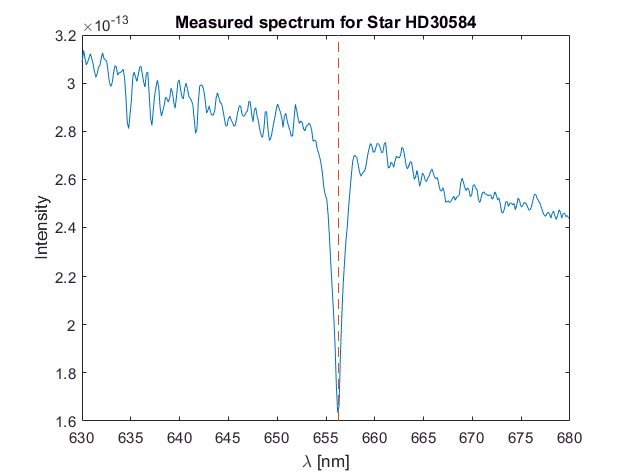

x = [656.28 656.28];
y = [1.6e-13 3.2e-13];
hold on
plot(x,y,'--')
hold off

## 6. Create meanFlux = average of HD30584

Create a variable `meanFlux` that contains the average (arithmetic mean) of `HD30584`.

meanFlux = mean(HD30584);

## 7. Calculate the absolute difference between the flux and mean

Use the `abs` function to calculate the absolute difference between the flux (`HD30584`) and its mean (`meanFlux`).

anomaly = abs(HD30584 - meanFlux);

## 8. Plot the anomaly vs wavelength

Plot the anomaly calculated in the last step as a function of wavelength (`lambda`).

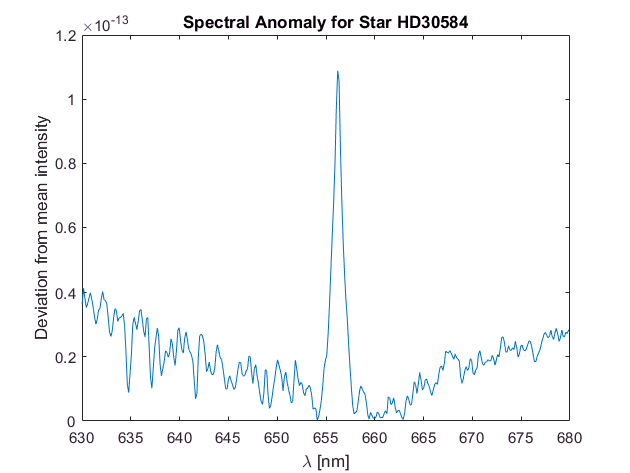

plot(lambda,anomaly)
title('Spectral Anomaly for Star HD30584')
xlabel('\lambda [nm]')
ylabel('Deviation from mean intensity')

## 9. Find the wavelength of the maximum anomaly

Find the wavelength of the maximum anomaly. (**Hint** Remember that the `max` function can optionally return the index of the maximum value.)

[maxAnom,idx] = max(anomaly);
Halpha = lambda(idx)

Halpha = 656.2000

## 10. Calculate the redshift

Calculate the redshift $z = \lambda_{max}/656.28 -1$, where $\lambda_{max}$ is the wavelength calculated in the previous step. From this, calculate the speed (in km/s) of the star relative to Earth, by multiplying z by 300000 (the approximate speed of light in km/s).

(The actual measurements used in this exercise are too coarse to determine a particularly accurate value of the speed.)

z = Halpha/656.28 - 1

z = -1.2190e-04

speed = z*300000

speed = -36.5698